# MF4 Can Data Extraction 

First Runs file mf4files which compiles all the data from the MF4 file time. Then it extracts it and puts it into time table so it can be plotted.

clear
filename = "dev1_11_17_7_14pm.MF4"
% load('DEV1_Combined_11_17_test.mat')

Position.Timestamp = Position.Timestamp - hours(5) + minutes(33) + seconds(47);
Acceleration.Timestamp = Acceleration.Timestamp - hours(5) + minutes(33) + seconds(47);
AngularVelocity.Timestamp = AngularVelocity.Timestamp - hours(5) + minutes(33) + seconds(47);
Orientation.Timestamp = Orientation.Timestamp - hours(5) + minutes(33) + seconds(47);

Position.Timestamp.TimeZone = "America/New_York";
Orientation.Timestamp.TimeZone = "America/New_York";
AngularVelocity.Timestamp.TimeZone = "America/New_York";
Acceleration.Timestamp.TimeZone = "America/New_York";


N1_TPDO0.Time.TimeZone = "America/New_York";
N1_TPDO1.Time.TimeZone = "America/New_York";
N1_TPDO2.Time.TimeZone = "America/New_York";

N10_TPDO0.Time.TimeZone = "America/New_York";
N10_TPDO1.Time.TimeZone = "America/New_York";
N10_TPDO2.Time.TimeZone = "America/New_York";
N10_TPDO3.Time.TimeZone = "America/New_York";



% mf4files
% data_min_max

Below are the plots for all the data that was extracted from the MF4 file.

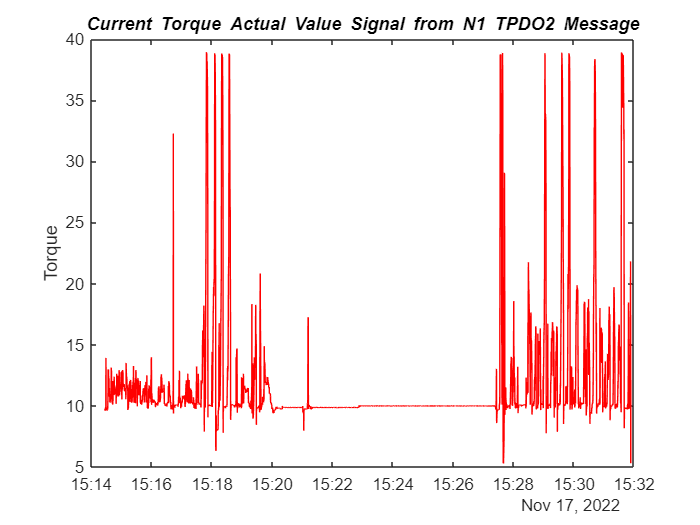

figure
% subplot(2, 1, 1)
plot(N1_TPDO2.Time, N1_TPDO2.Current_Torque_Actual_Value/100, "r")
title("{\itCurrent Torque Actual Value} Signal from {\itN1 TPDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Torque")

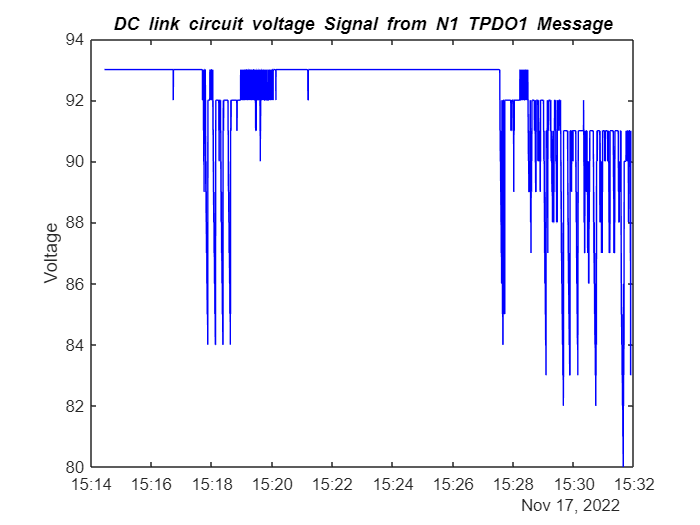

% subplot(2, 1, 2)
figure
plot(N1_TPDO1.Time, N1_TPDO1.DC_link_circuit_voltage/10, "b")
title("{\itDC link circuit voltage} Signal from {\itN1 TPDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Voltage")

figure
% subplot(2, 1, 1)
% plot(N1_TPDO2.Time, N1_TPDO2.Electrical_angle, "y")
% title("{\itElectrical angle} Signal from {\itN1 TPDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
% ylabel("Angle")
% subplot(2, 1, 1)
% plot(N1_TPDO0.Time, N1_TPDO0.Position_actual_value, "g")
title("{\itVelocity Actual Value} Signal from {\itN1 TPDO0} Message", "FontWeight","bold")
xlabel("Timestamp")

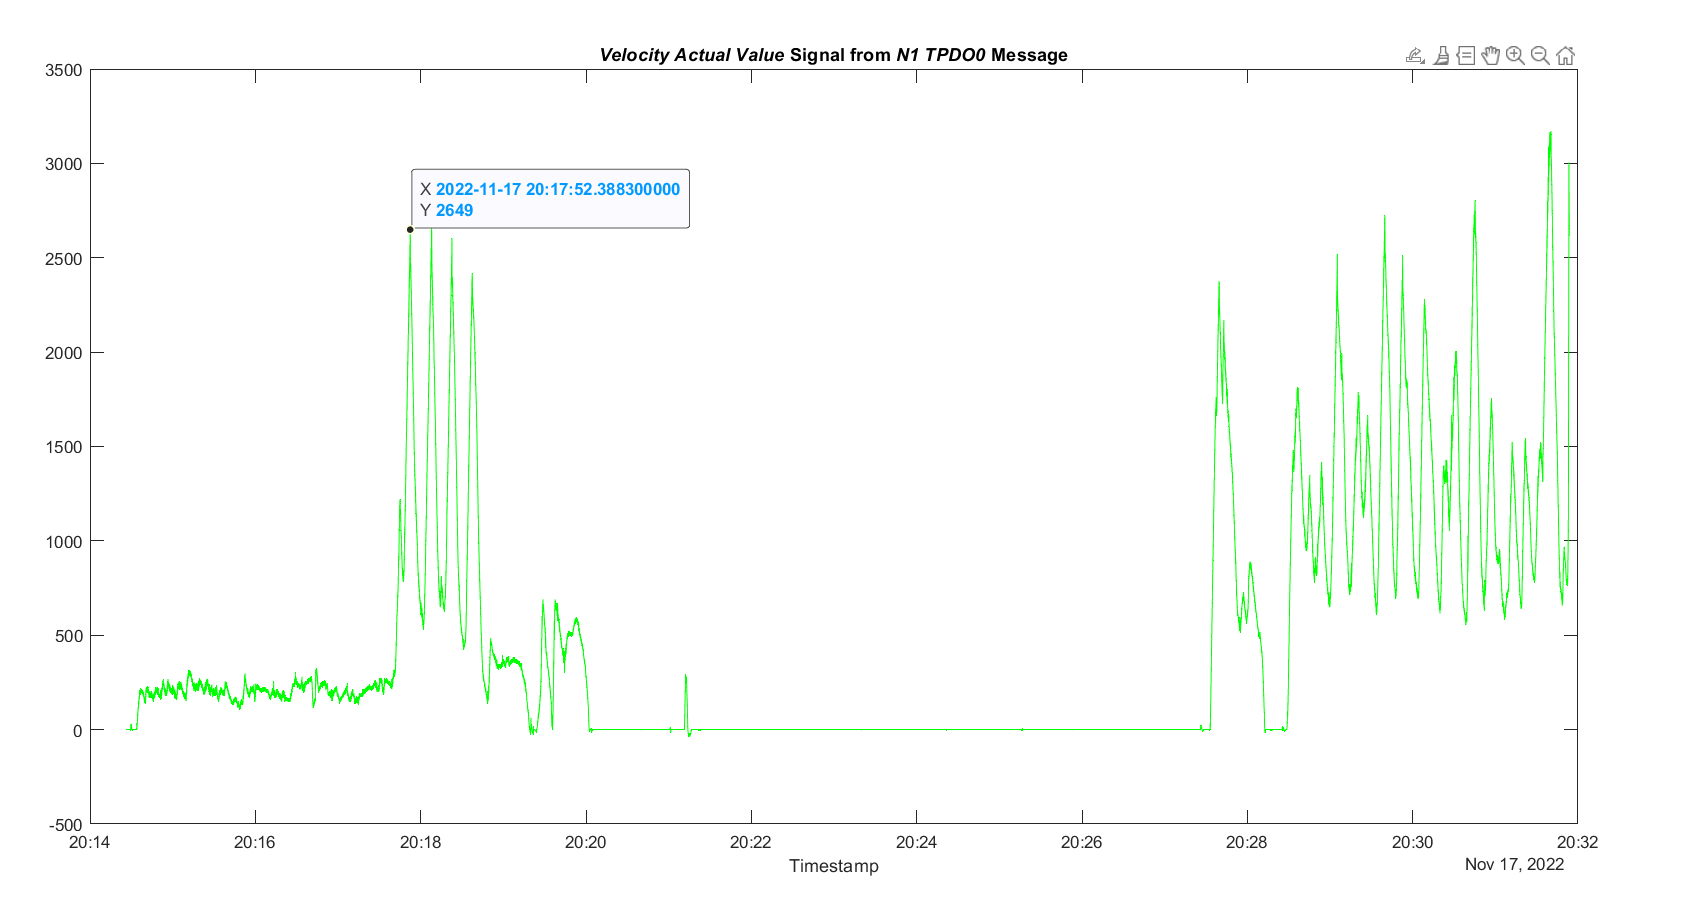

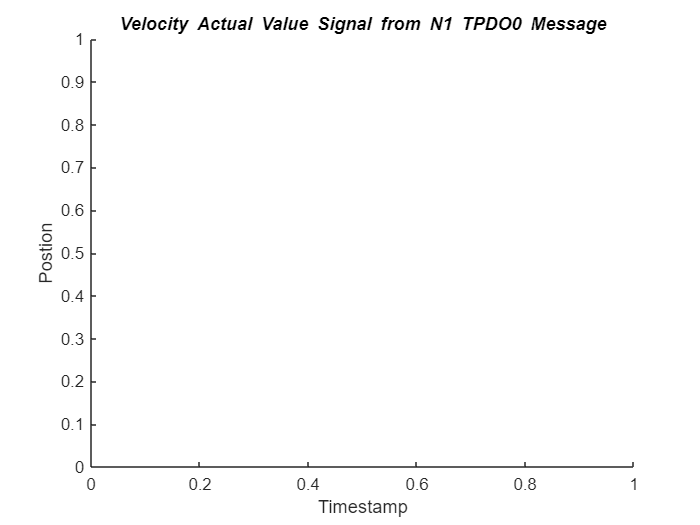

ylabel("Postion")

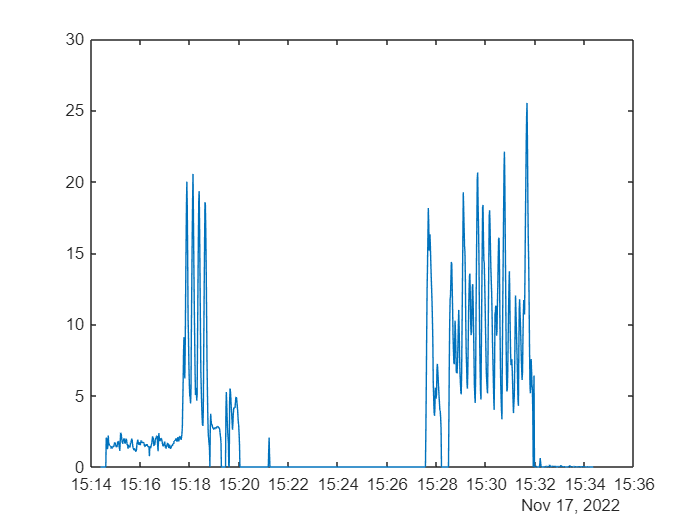

% 
% xlim([datetime(2022,11,17,20,17,50.5,"TimeZone","UTC")...
%       datetime(2022,11,17,20,17,54.4,"TimeZone","UTC")])
% ylim([2640.5 2654.9])
% ax = gca;
% chart = ax.Children(1);
% datatip(chart,datetime(2022,11,17,20,17,52.3883,"TimeZone","UTC"),2649);
figure
plot(Position.Timestamp, Position.speed)

% 
% xlim([datetime(2022,11,17,20,17,29)...
%       datetime(2022,11,17,20,19,43)])
% ylim([18.06 21.11])
% ax2 = gca;
% chart2 = ax2.Children(1);
% datatip(chart2,datetime(2022,11,17,20,17,52.999),20.01);

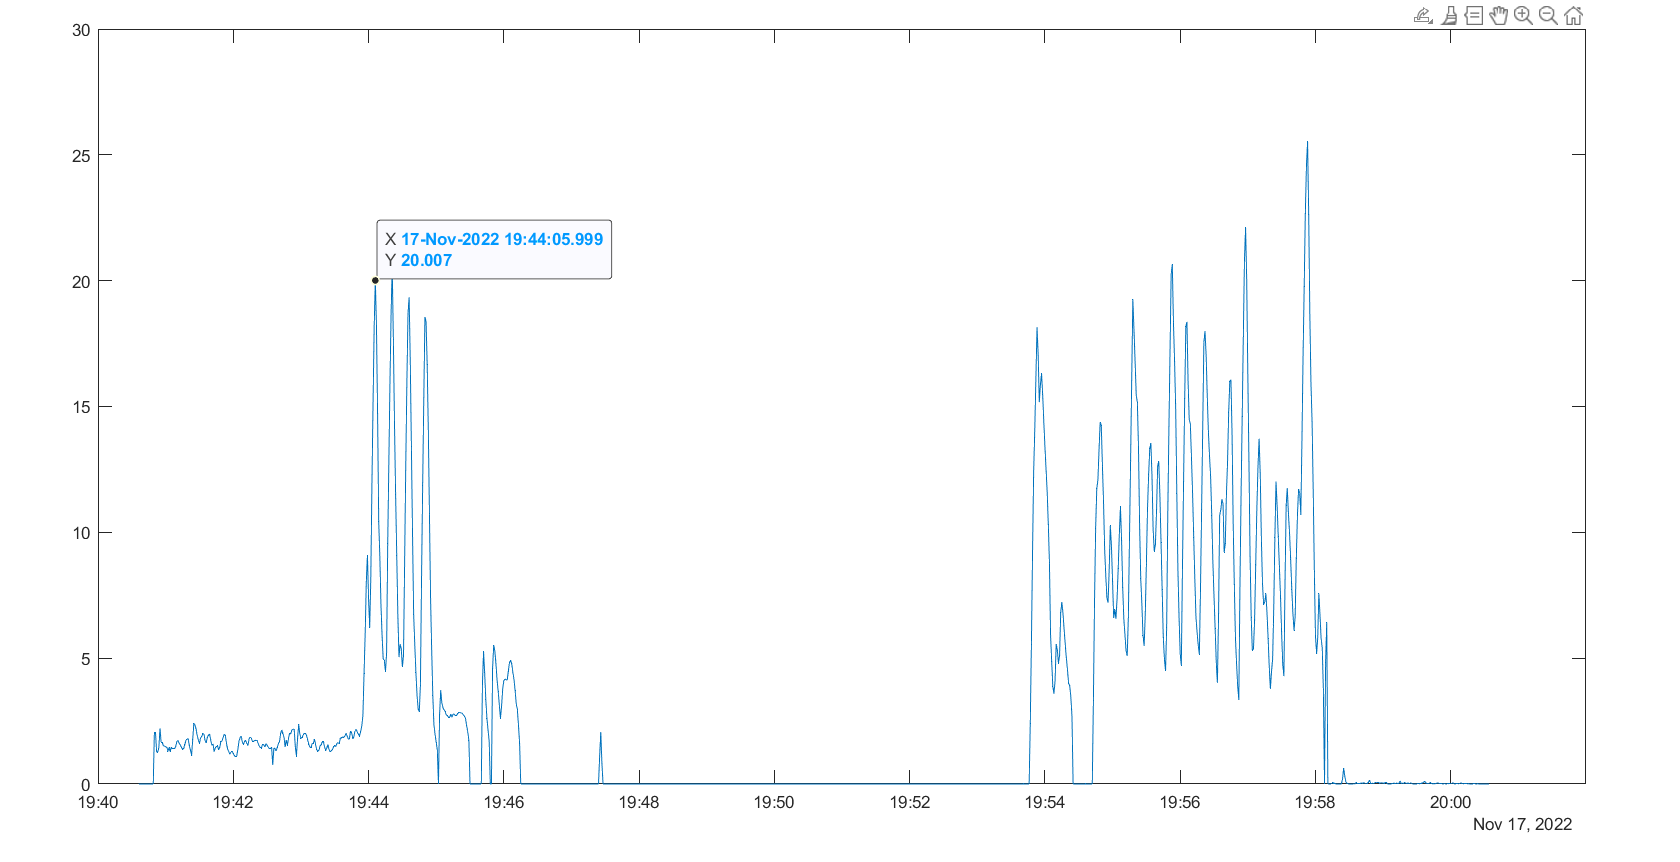

This is all data captured from the Inverter

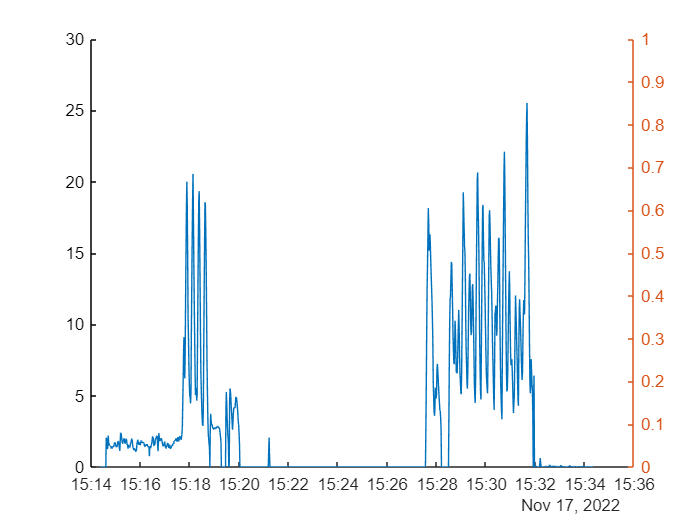

% minmaxtable1

figure
hold on
plot(Position.Timestamp, Position.speed)
yyaxis right

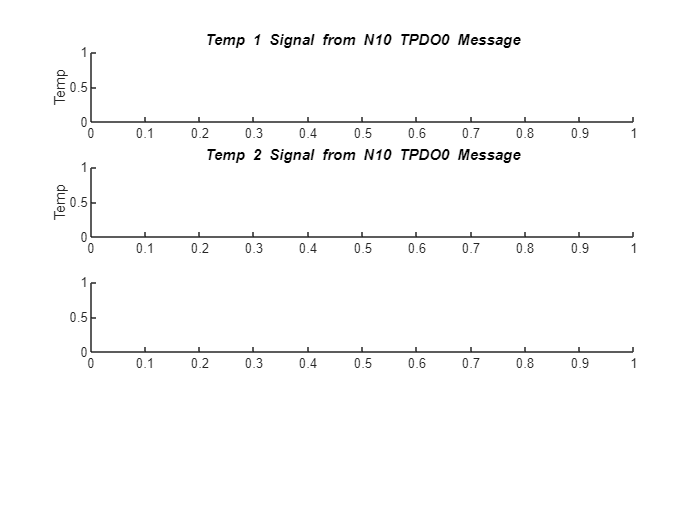

% plot(N1_TPDO0.Time, N1_TPDO0.Position_actual_value, "g")
figure
subplot(4, 1, 1)
% plot(N10_TPDO0.Time, N10_TPDO0.Temp_1/1000, "r")
title("{\itTemp 1} Signal from {\itN10 TPDO0} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Temp")

subplot(4, 1, 2)
% plot(N10_TPDO0.Time, N10_TPDO0.Temp_2/1000, "b")
title("{\itTemp 2} Signal from {\itN10 TPDO0} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Temp")

subplot(4, 1, 3)

plot(N10_TPDO1.Time, N10_TPDO1.Temp_3/1000, "y")

Unable to resolve the name 'N10_TPDO1.Time'.

title("{\itTemp 3} Signal from {\itN10 TPDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Temp")

subplot(4, 1, 4)
plot(N10_TPDO1.Time, N10_TPDO1.Temp_4/1000, "g")
title("{\itTemp 4} Signal from {\itN10 TPDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Temp")
% minmaxtable2

This is all tempeture readings captured from the tempture sensors

%%%

figure
% subplot(4, 1, 1)
plot(N10_TPDO2.Time, N10_TPDO2.Volt_1/1000, "r")
title("{\itVolt 1} Signal from {\itN10 TPDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
% ylabel("Volts")

% subplot(4, 1, 2)
plot(N10_TPDO2.Time, N10_TPDO2.Volt_2/1000, "b")
title("{\itVolt 2} Signal from {\itN10 TPDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
% ylabel("Volts")

% subplot(4, 1, 3)
plot(N10_TPDO3.Time, N10_TPDO3.Volt_3/1000, "y")
title("{\itVolt 3} Signal from {\itN10 TPDO3} Message", "FontWeight", "bold")
% xlabel("Timestamp")
% ylabel("Volts")

% subplot(4, 1, 4)
plot(N10_TPDO3.Time, N10_TPDO3.Volt_4/1000, "g")
title("{\itVolt 4} Signal from {\itN10 TPDO3} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Volts")
% minmaxtable3

This is all voltage readings captured from the tempture sensors

figure
subplot(3, 1, 1)
plot(N1_TPDO0.Time, N1_TPDO0.Statusword, "r")
title("{\itstatusword 1} Signal from {\itN1 TPDO0} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("")

subplot(3, 1, 2)
plot(N1_TPDO1.Time, N1_TPDO1.Motor_temperature, "b")
title("{\itMotor Temperature} Signal from {\itN1 TPDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Degrees Celsius")

subplot(3, 1, 3)
plot(N1_TPDO1.Time, N1_TPDO1.Controller_temperature, "y")
title("{\itController Temperature} Signal from {\itN1 TPDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Degrees Celsius")
clear ans canData canDB mdfObj msgTimetable signalTimetable
% clear N10_TPDO0 N10_TPDO1 N10_TPDO2 N10_TPDO3
save('DEV1_Combined_11_17_test_processed.mat')